# Wave Parameter Extraction Pipeline

This MATLAB LiveScript serves as a live document to show the implementation of the SAR wave parameter extraction pipeline with additional documentation. Documentation notes are included before code blocks which explain the code which follows.

## Prerequisites

Python 3.8 (Need to check version in MATLAB)

pe = pyenv;
pyVersion = pe.Version;
if ~(strcmp(pyVersion, "3.8"))
    pe(Version="3.8")
end

CDS Toolbox

MMap? (Maybe)

wgrid

## Obtain SAR Data

[SNAP ESA](https://step.esa.int/main/download/snap-download/)

[Copernicus SciHub](https://scihub.copernicus.eu/dhus/#/home)

## **Pre-Process SAR Data**

## Take transects and subdivide

After exporting the SAR data as a netCDF file, use the following commands to import the data and metadata into MATLAB.

filepath = "D:\UCT\EEE4022S\Data\CPT\small_subset.nc";
% Import data values
ncImport = ncinfo(filepath);
% Update the band to import as required
VV = ncread(filepath,'Sigma0_VV');

Enter the number of desired transects to take, the start point (in pixels), along with the angle at which to take the transects. This angle is calculated from the positive x-axis clockwise.

% Enter the number of transects
n = 3;
th = 35;
[transectData, positions] = get512Transects(VV,1,1,th,n);

The original data, with shown transects can be plotted as follows.

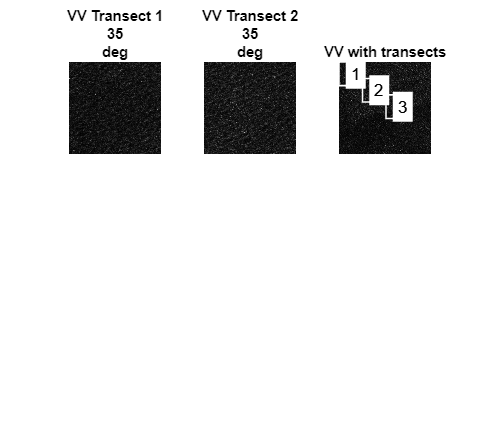

figure(1)
imshow(VV)
hold on;

for i = 1:n
    annotate512Transect(positions(i,1),positions(i,2),i,'w','black',1);
end

title('VV with transects')
hold off

The individual transects can be plotted as follows.

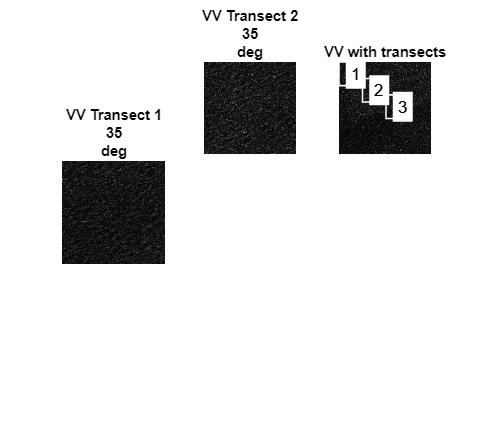

figure(2)
subplot(1,3,1)
imshow(transectData(:,:,1));
title(["VV Transect 1",th,"deg"])

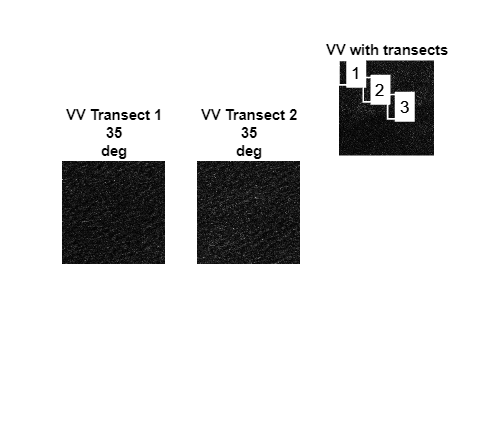

subplot(1,3,2)
imshow(transectData(:,:,2));
title(["VV Transect 2",th,"deg"])

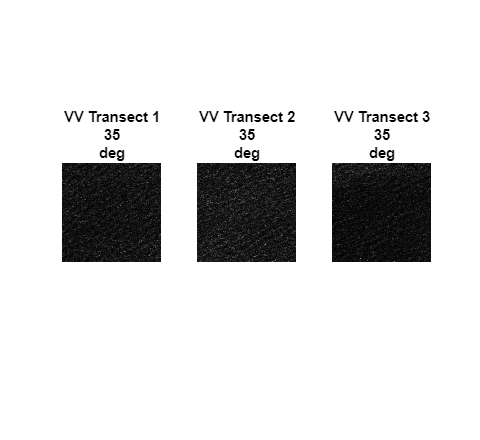

subplot(1,3,3)
imshow(transectData(:,:,3));
title(["VV Transect 3", th,"deg"])

Metadata can be imported using the ncinfo function. This large metadata structure can be slimmed down by filtering using the desired attributes for subsequent functions.

% Metadata
metadata = ncinfo(filepath,'metadata');
req_atributes = ["first_near_lat","first_near_long","first_far_lat","first_far_long","last_near_lat","last_near_long","last_far_lat","last_far_long","centre_lat","centre_lon", "num_output_lines","num_samples_per_line"];
metadata_filtered = filterAttributesNetCDF(metadata.Attributes, req_atributes);

## Metadata Extraction

## SAR Spectrum Calculation

## Hasselmann Inversion Procedure

## Output Parameters